# Vision: YOLO

In this notebook we will learn to perform extract images to train the Yolo detector.

# 0. Connect to the Simulation

We will open up the UR simulation in gazebo.

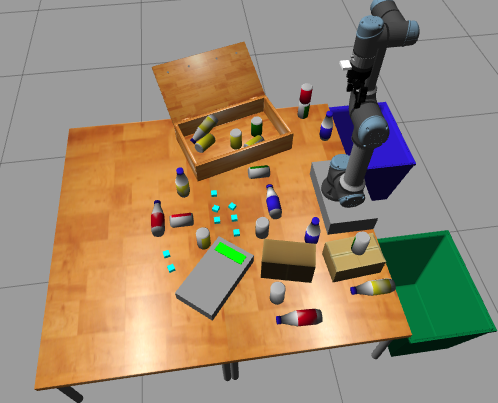

## 0.1 Run your Virtual Machine

Start the armgazebo container. 

## 0.2 Run your Container

Call **run.bash** from [src/arm_gazebo/docker](http://www.google.com):

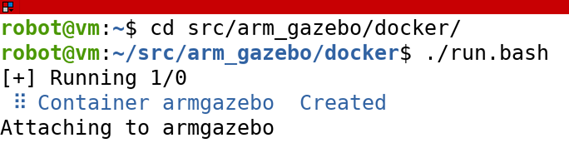

Also retrieve your hostname via command: hostname -I

### 0.3 Connect MATLAB to Gazebo using the ROS Toolbox

Note: for connections inside Lipscomb's network make sure you have already updated your hosts files by setting the IP address above followed by VM.

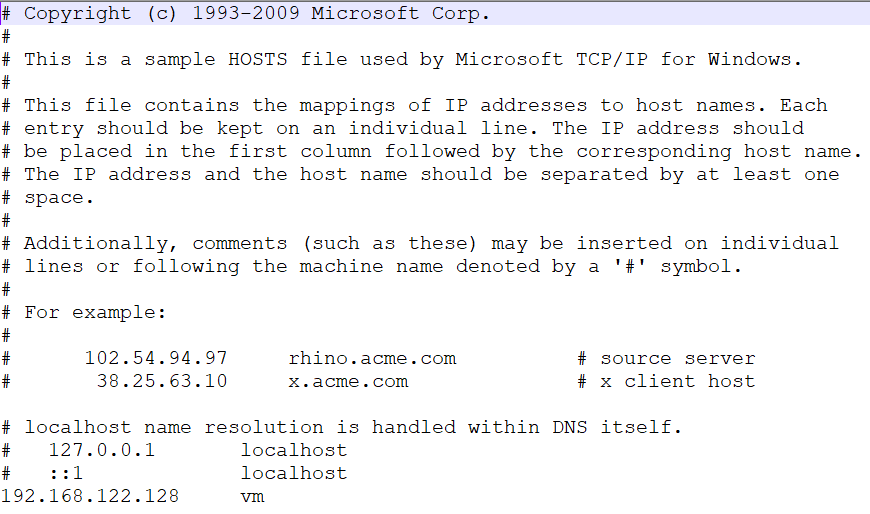

Call rosinit with:

- ip of vm

- port number 11311

- 'NodeHost' declaration

- ip of node host

rosinit('192.168.56.101',11311,'NodeHost','192.168.56.1');

# 1. Data Collection

From our master ros_matlab code, change directory to the _vision/yolo folder.

The script `collect_yolo_data.m` selects a model and then calls `collect_obj_images. `The later will move the arm in concentric circles around the object taking pictures from different angles. There are 3 main parameters: 

- a rotation offset (determines the number of points to visit around the circle), 

- a linear offset (the distance from the center of the object at which to go around the circle), and 

- the number of iterations (the number of concentric circles at increasing offsets to execute).

#### Noise

Noise is injected into both the rotational and linear offsets to create different trajectories and as a result sets of images. This increased diversity should help with better training data.

#### **Caveats**

It is possible, that some images may not contain a can. That is, where the noise might have driven the arm a bit too far away from the can. These images will be labeled as null.

#### Image Names

The resulting images will be saved in a single image structure that will be saved in a data folder inside yolo. Thelink name of the file uses the input model name to encode a name with the following pattern:

    color_objectType_yyyymmdd_HHMMSS.mat

This script can be run in two modalities:

1. Circular arm motions

- Have a center object and other objects surrounding it. This allows us to collect data from multiple objects at the same time (the scenes need to be prepared in parallel with staging fazebo files).

- Or just a single file.

2. Side-to-side arm motions

- The script can also be expanded to scan the original gazebo worlds from side-to-side to capture many objects in one shot. This is the prefered method (it will be left up to you to create the side-to-side script).

Note: try to have an **equal number of images** for all the objects in order to have a **more balanced dataset**.

## 1.1 Merging multiple Images

After you have generated multiple image structures (.mat files), you can merge them with the `merge_img_structures.m` script/function. 

All your existing image structurse will be the input to the function, set the output as **yoloTrainingData **and save it also as a ".mat" file.

Each time will be tasked to work with different objects. When you finish and obtain your final image structure, upload it to the following google drive link. We will use it to train the detector: [https://drive.google.com/drive/folders/1VQpBL9mi5HoMyaXcK60UaEWurd0Bp731?usp=sharing](https://drive.google.com/drive/folders/1VQpBL9mi5HoMyaXcK60UaEWurd0Bp731?usp=sharing) 

# 2. Training the Yolo Network 

## 2.1 Labeling Images

All the images we have taken, need to be labeled using the [Image Labeler](docid:vision_ref.mw_96fe579b-b33c-4798-a463-6fdeee7cd214) app, creating the training dataset for the YOLO v4 detection model. The app provides an easy way to interactively create a variety of shapes to mark as region of interest (ROI) labels

A typical individual project would consist of:

- Load new or partially labeled images or a saved project

- Create a datastore for images

- Define labels using the app or programmatically via the method [`labelDefinitionCreator`](https://www.mathworks.com/help/vision/ref/labeldefinitioncreator.html)

- Create ROI

- Create Labels

- Export the labled images as a groundTurth or tained_data table to train the network.

- Save the session as an individual/team project. 

We will review these steps for now. Then we will be interested in: "Create Team-Based Image Labeling Project":

- [https://www.mathworks.com/help/vision/team-based-image-labeling.html](https://www.mathworks.com/help/vision/team-based-image-labeling.html)

- [https://www.mathworks.com/help/vision/ug/get-started-with-team-based-labeling.html](https://www.mathworks.com/help/vision/ug/get-started-with-team-based-labeling.html) 

For additional resources on Image Labeler see:

- [https://www.mathworks.com/help/vision/ug/get-started-with-the-image-labeler.html](https://www.mathworks.com/help/vision/ug/get-started-with-the-image-labeler.html) 

- [https://www.mathworks.com/help/vision/ug/getting-started-with-yolo-v4.html](https://www.mathworks.com/help/vision/ug/getting-started-with-yolo-v4.html) 

- [https://blogs.mathworks.com/student-lounge/2020/07/07/yolov2-object-detection-data-labelling-to-neural-networks-in-matlab/](https://blogs.mathworks.com/student-lounge/2020/07/07/yolov2-object-detection-data-labelling-to-neural-networks-in-matlab/) 

In this step we will draw bounding boxes around images that were generated by our col`lect_yolo_data.m` script. Remember 

**Step 1: Labeling Images in the Image Labeler App**

#### **Open the Image Labeler App**

- In MATLAB, you can open the Image Labeler app by typing `imageLabeler` in the Command Window.

                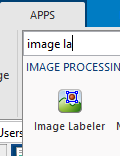 

#### **Import your images**

- I have create a script to take your .mat files with image structures inside and save all images inside as files. Use _vision/yolo/save_img_structures_to_file.m to convert all ./yolo/data/*.mat files to images

- Import these images into the app:

            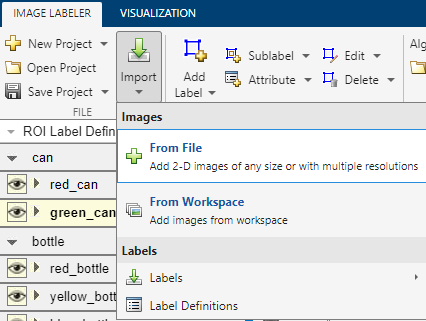 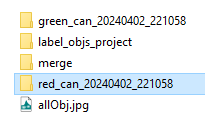   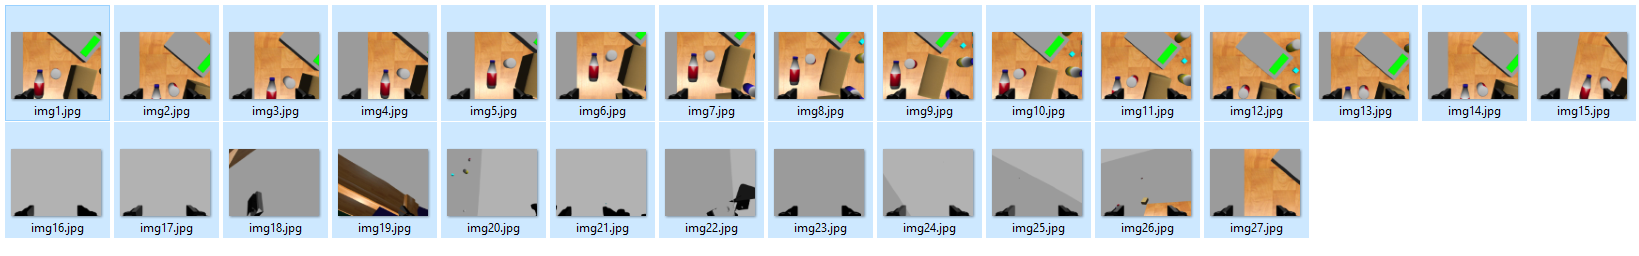

**Create Labels**

- We are interested in creating 7 to 9 classes: red_can, green_can, yellow_can, red_bottle, blue_bottle, yellow_bottle, pouch, and (wood_case_ box, box). We can also create 4 groups: cans, bottles, pouches, boxes. 

                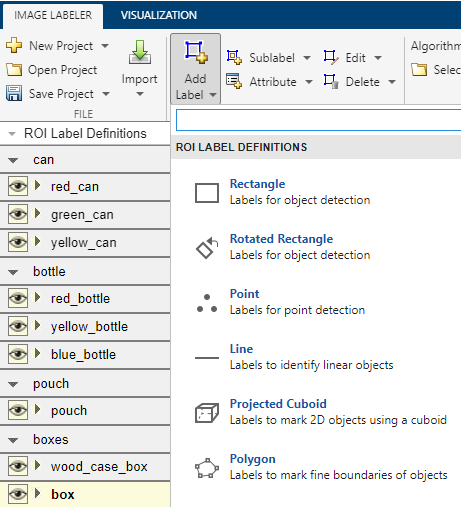

- Create label | group | color for your cans, bottles, pouches, and boxes. 

                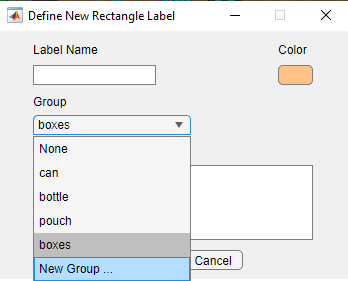

**Label Your Images**

- After creating all your labels, (i) select an image to label, (ii) click on a pre-existing label on the left side of the pane, (iii) directly click on the image and drag a bounding box around object that matches the label you clicked on. (iv) repeat for all your images. 

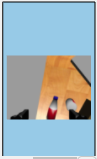   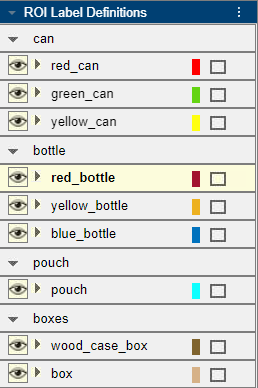  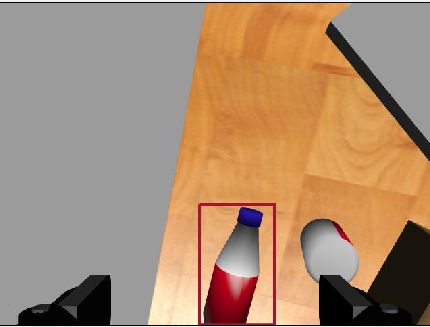

#### Export Ground Truth Table

- After finishing, you are ready to export your images as a table. 

- Save to file and to workspace. 

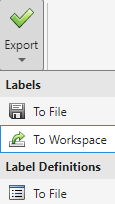 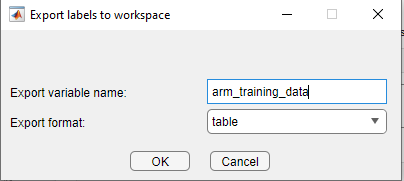

We will end with a two-column table. The first column contain the image file paths and the second column contain the bounding boxes.

## 2.2 Preprocessing Data

### 2.2.1 Get Data into Matlab

Once you have finished labeling your images with bounding boxes and labels, you can export that dataset to file/workspace. Let's call it arm_training_data. 

baseFolder = "C:\Users\jlrojassuarezdelreal\OneDrive - lipscomb.edu\school\teaching\eece4513-robotics\lecs\ros_matlab\code";
datasetFolder = "_vision/yolo/data";
cur_path = fullfile(baseFolder,datasetFolder);

trainingData = arm_training_data; % Class table

Description:  This was created using the Image Labeler app on 05-Apr-2024.

Variables:

    imageFilename: 21×1 cell array of character vectors

    green_can: 21×1 cell

    red_can: 21×1 cell



%unresolvedPaths = changeFilePaths(trainingData.imageFilename, fullfile(,datasetFolder));

Display the data set summary.

summary(trainingData);

This table has n+1 columns where n is the number of classes. The table is organized as follows:

- Col 01: imageFilename is a string that contains the path to the filename

- Col 02 to n: bounding box for object with label of that column. 

Note: bounding boxes are defined as follows: [xmin, ymin, width, height.]

### 2.2.2 Create Training, Validation, and Testing Datasets

Randomly shuffle data for training. Split the dataset into training, validation, and test sets. Select 60%  of the data for training, 10% for validation, and the rest for testing  the trained detector.

rng(0);
shuffledIndices = randperm(height(trainingData)); % Get table height and permute entries

idx = floor(0.6 * length(shuffledIndices) );

% Training Data
trainingIdx = 1:idx;
trainingDataTbl = trainingData(shuffledIndices(trainingIdx),:);

% Validation Data
validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = trainingData(shuffledIndices(validationIdx),:);

% Test Data
testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = trainingData(shuffledIndices(testIdx),:);

#### 2.2.3 Create Datastores

Datastores in MATLAB are a powerful and flexible way to manage large  collections of data, particularly when the data is too large to fit into memory all at once. A datastore is an object that enables you to read  and process data in chunks, making it possible to work efficiently with  big data. The concept is crucial for data analytics, machine learning,  and any application requiring the manipulation of large datasets. 

MATLAB datastores can handle a variety of data formats, including but  not limited to text files (CSV, TSV), images, spreadsheets, and binary  files. Specialized datastores are available for specific data types,  like `ImageDatastore` for image data, `TabularTextDatastore` for tabular text data, etc.

Use `imageDatastore` and `boxLabelDatastore` to create datastores for loading the image and label data during training and evaluation.

**Training Datastore**

imdsTrain = imageDatastore(trainingDataTbl.imageFilename);
bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:end));

**Validation Datastore**

imdsValidation  = imageDatastore(validationDataTbl.imageFilename);
bldsValidation  = boxLabelDatastore(validationDataTbl(:,2:end));

**Testing Datastore**

imdsTest  = imageDatastore(testDataTbl.imageFilename);
bldsTest  = boxLabelDatastore(testDataTbl(:,2:end));

**Combine image and box label datastores**

These structures should contain: (i) image, (ii) bounding box(es), (iii) label(s). By combining our image and bboxes we arrive at the form we will use to train, validate, and test the system.

trainingData    = combine(imdsTrain,bldsTrain);
validationData  = combine(imdsValidation,bldsValidation);
testData        = combine(imdsTest,bldsTest);

For debugging purposes, display one of the training images and box labels

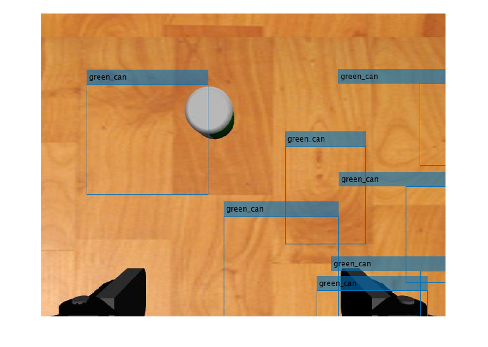

data = read(trainingData);

I    = data{1};
bbox = data{2};
labels = data{3};

% Extract class names for this training sample
classNames = arm_training_data.Properties.VariableNames(2:end);

% Create colors for labels
label_colors = im2uint8(lines( numel(classNames)) );

% Convert labels to categorical type
labels = categorical(labels,classNames); 

% Insert bbox, label, and color to image
annotatedImage = insertObjectAnnotation(I, 'Rectangle', ...
                                        bboxes, cellstr(labels),...
                                        'Color',label_colors(int32(labels),:));

annotatedImage = imresize(annotatedImage,2);

figure
imshow(annotatedImage)

Reset your training data:

reset(trainingData);

## 2.3. Create a YOLO v4 Object Detector Network

To create the YOLO v4 object detector by using the `yolov4ObjectDetector` function. We will first have to specify the following information:

- image input size [MxNx3]

- class names {class1, class2, classN}

- estimated anchor boxes (see below)

- the name of a pretrained YOLO v4 detection network: 

-     "detector_gral_sim.mat" or 

-     "tiny-yolov4-coco" or 

-     "csp-darknet53-coco".

### 2.3.1 Set the network input size:

ROS is outputing square images of size [480,640,3].

inputSize = [480,640,3];

### 2.3.2 Set the classes labels in a cell array. 

Class labels will need to match the ground truth labels produced during the labeling. The process may change as you do more sophisticated training.

classNames = arm_training_data.Properties.VariableNames(2:end)

classNames = 1×2 cell array
    {'green_can'}    {'red_can'}


### 2.3.3 Specify Achor Boxes

Anchor boxes are predefined bounding boxes that have been designed to predict the shapes and sizes of objects in an image. Their main purposes are:

- **To Predict Multiple Objects per Grid Cell**: Originally, YOLO divides the image into a grid, and each grid cell was responsible for predicting only one object. This could lead to problems when multiple objects fell within a single cell. Anchor boxes allow each grid cell to predict multiple objects by associating each object with the best matching anchor box.

- **To Handle Different Object Shapes and Sizes**: By defining anchor boxes of various aspect ratios and sizes, YOLO can more accurately predict objects that vary significantly in shape and size, from tall and narrow to short and wide.

**Determination Before Training**

- **Predefined Sizes**: Anchor boxes are predefined and fixed in number. Their sizes and ratios are typically chosen based on common shapes and sizes of objects in the training dataset. Sometimes, k-means clustering on the training set bounding boxes is used to automatically determine the most representative anchor boxes.

- **Used During Training and Inference**: The model learns to adjust these anchor boxes to match the actual objects during training. For each anchor box, the model predicts adjustments to the box's position and dimensions, as well as the object class.

**Spacing and Stride**

- **Grid and Stride**: The image is divided into a grid (e.g., 13x13, 26x26), and each grid cell is responsible for predicting objects whose center falls within the cell. The stride refers to the step in pixels between grid cells in the original image. For example, if the input image is 416x416 pixels and the grid size is 13x13, the stride is 32 pixels (416/13).

- **Scale-Specific Anchors**: YOLOv3 and later versions use multiple scales to detect objects. Smaller anchor boxes are used at higher resolutions (fine-grained features) to detect smaller objects, and larger anchor boxes are used at lower resolutions (coarse features) to detect larger objects. This multiscale approach is designed to improve the detection of objects of varying sizes.

**How They Work**

During training and inference:

- Each grid cell uses its anchor boxes to predict bounding boxes for objects. The model outputs adjustments to the anchor boxes (e.g., scale and aspect ratio adjustments) to better fit the actual objects.

- Each prediction includes confidence scores for objectness (whether an object is present) and class probabilities.

- The "best matching" anchor box for a given object during training is usually the one with the highest IoU (Intersection over Union) with the ground truth bounding box.

**Connecting Anchor Boxes to the YOLO Net**

- In order for a grid cell to use an anchor box, it actually has to be connected to a detection head in the yolo network. 

- The thought is to choose anchors of different sizes (defined by width and height) and assign a set of them to each of the detection heads. Imagine you have 9 different anchors: a small set, a medium set, a large set. You can assign a set to a detection head. 

- In effect, one detection head will have 3 'smaller anchors' for 'small' objects, another 3 'middle anchors' for 'middle' sized objects, and the last one 3 'large anchors' for 'large' objects. 

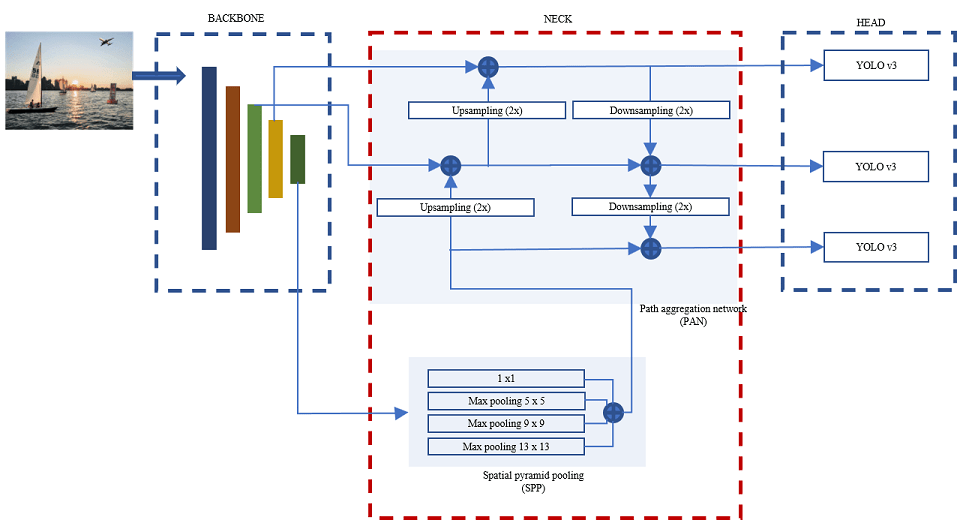

**Creating a fixed number of Anchor Boxes before Training**

YOLO requires a developer to set a predefined number of anchor boxes per grid for each class. If you choose to segment the image in 9 cells, you would then have 9 anchor boxes * #  of classes per grid.  The image below shows an example where there are 16... 

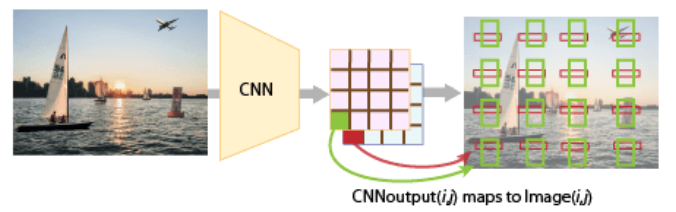

After training the network will actually learn to resize all of these boxes to fit the objects appropriately. These serve as a baselines to start training the system.

**Summary**

To summarize, anchor boxes in YOLO:

- Allow the detection of multiple objects per grid cell.

- Enable the model to handle objects of various shapes and sizes efficiently by assigning anchors of different sizes to the network's heads.

- Require predefinition based on the dataset and are integral during both training and inference for predicting object bounding boxes.

#### **2.3.3.1** **Preprocess Data**

To avoid scaling problems, images are resized by scaling pixels between 0 and 1. Bounding boxes are also scaled correspondingly.

rng("default")
trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));

#### 2.3.3.2 Estimate the Number of Anchor Boxes You Need

Consider all the different sized boxes that you need to identify all cans, bottles, pouches and boxes. Could you choose a base number? The [`estimateAnchorBoxes`](https://www.mathworks.com/help/vision/ref/estimateanchorboxes.html) function estimates number of anchor boxes based on the size of objects in the  training data. 

Increasing the number of anchor boxes can improve the mean IoU measure. However, using more anchor boxes in an object detector can also increase the computation cost and lead to overfitting, which results in poor detector performance.

Below we will test the performance of the system when the number of anchor boxes changes. We use the mean IoU as a metric versus number of anchor boxes to measure the trade-off between number of anchors and mean IoU. Try to identify the number of anchor boxes that give you the biggest marginal IoU gain without overfitting:

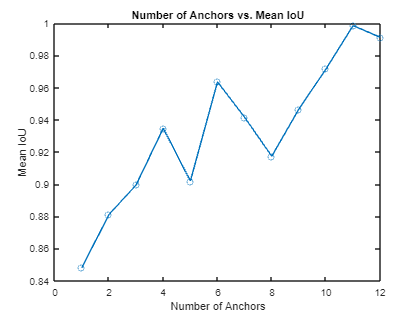

maxNumAnchors = 12;

meanIoU         = zeros([maxNumAnchors,1]);
anchorBoxes     = cell(maxNumAnchors, 1);

for k = 1:maxNumAnchors
    [anchorBoxes{k}, meanIoU(k)] = estimateAnchorBoxes(trainingDataForEstimation,k);    
end

figure, plot(1:maxNumAnchors,meanIoU,'-o');
xlabel("Number of Anchors"), ylabel("Mean IoU"), title("Number of Anchors vs. Mean IoU");

Analyze your plot and try to find a value that gives you the greatest gain without overfitting

best_num_anchors = 9;      % Adjust the number here based on results. Nice if divisible by 3 (will use later).
anchors = anchorBoxes{best_num_anchors}; 

#### 2.3.3.3 Sort Anchor Sizes based on Area

Specify the `anchorBoxes` for each detection head based on the feature map size. Use larger anchors at lower scale  and smaller anchors at higher scale. To do so, sort anchors by area, in  descending order, and assign the first three to the first detection head and the last three to the second detection head.

Use larger anchors at lower scale and smaller anchors at higher scale.  To do so, sort anchors by area, in descending order, and assign the  first three to the first detection head and the last three to the second detection head.

- Head 1: 3x80x80x117 -> detects **small size objects**

- Head 2: 3x40x40x117 -> detects **medium size objects**

- Head 3: 3x20x20x117 -> detects **large size objects**

% Compute the area of all your anchor boxes by multiplying their width * height
area = anchors(:,1).*anchors(:,2); % N anchors: [width height]

% Sort the areas from large to small
[~,idx] = sort(area,"descend");

% Set them as sortedAnchors
sortedAnchors = anchors(idx,:);

#### 2.3.3.4 Assign small, med, large anchors to each of the 3 YOLO net heads

There are three detection heads in the YOLO v4 network, so make three sets of best_num_anchors/3 anchor boxes each.

See more at [https://medium.com/@onkar.cho1/story-of-anchors-and-grids-in-yolo-68efb7a1a04b](https://medium.com/@onkar.cho1/story-of-anchors-and-grids-in-yolo-68efb7a1a04b) 

thresh = round(best_num_anchors/3);
anchorBoxes = {sortedAnchors( 1             :thresh,     :)...
               sortedAnchors( (thresh+1)    :(2*thresh), :)...
               sortedAnchors( ((2*thresh)+1):(3*thresh), :)};

#### 2.3.4 Training Data Augmentation

This is an optional setp but data augmentation improves training accuracy. Use the `transform` function to apply custom data augmentations to the training data. The `augmentData` helper function applies the following augmentations to the input data:

- Color jitter augmentation in HSV space

- Random horizontal flip

- Random scaling by 10 percent

**Note**:

Data augmentation is not applied to the test and validation data.  Ideally, test and validation data should be representative of the  original data and is left unmodified for unbiased evaluation.

networkInputSize = detector.InputSize;
preprocessedTrainingData = transform(trainingData, ...
                                     @(x)augmentDataKeepingAspectRatio(x,networkInputSize,doAugmentation));
reset(preprocessedTrainingData);

#### 2.3.5 Instantiate a YOLO v4 object detection network

Now that we have:

- input size,

- class names, and

- estimated anchor boxes,

We will just provide the name of the pretrained YOLO v4 detection network ("tiny-yolov4-coco" or "csp-darknet53-coco"). 

Before you complete this step, you will need to install an additional ComputerVisionToolbox required by Matlab for this newer model.As you try to run the command, matlab will prompt you.

pretrained_net = "csp-darknet53-coco"; % Or "tiny-yolov4-coco"
detector = yolov4ObjectDetector(pretrained_net);
%detector = yolov4ObjectDetector(pretrained_net,classNames,anchorBoxes,InputSize=inputSize);

#### Customize layers

% Creater a layer graph from detector (inputs, outputs, layers, connections)
lGraph = layerGraph(detector.Network);

% Createa  base network
baseNetwork = dlnetwork(lGraph);

% Set anchor boxes
anchorBoxes = detector.AnchorBoxes;

% Adapt Detector
detector = yolov4ObjectDetector(baseNetwork,...
                                classNames,...
                                anchorBoxes,...
                                'DetectionNetworkSource',...
                                detector.Network.OutputNames);

Intermediate dot '.' indexing produced a comma-separated list with 0 values, but it must produce a single value when followed by subsequent indexing operations.

Error in deep.internal.sdk.forwardDataAttributes>iForwardExampleInputsLayerGraph (line 250)
            plY{i} = layerAnalyzer.Outputs.Meta{1};

Error in <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('deep.internal.sdk.forwardDataAttributes', '/media/juan/sdd/matlab/R2024b/toolbox/nnet/cnn/+deep/+internal/+sdk/forwardDataAttributes.m', 69)" style="font-weight:bold">deep.internal.sdk.forwardDataAttributes</

Inspect the properties of the detector.

detector

Study the following fields:

- Network: tells you about the structure of the network

- AnchorBoxes: tells you sets of anchors boxes 

- ClassNames: existing labels for different classes 

- InputSize: the size of the input images

- ModelName: the name of the model

Read and display samples of augmented training data.

augmentedData = cell(4,1);
for k = 1:4
    data = read(preprocessedTrainingData); % Images | BBox | label
    augmentedData{k} = insertShape(data{1},"rectangle",data{2});

    % Reset datastore (read position reset; data shuffling reset)
    reset(preprocessedTrainingData);
end

figure,
montage(augmentedData,BorderSize=10); % display multiple images as a rect montage to show differences from augmented data

#### 2.3.6 Train the YOLO v4 Detector

Use `trainingOptions` to specify network  training options:

- Gradient descent technique: Adam 

- MaxEpochs: 80 

- Learning rate 0.001. 

- To train with lowest validation loss set `OutputNetwork` = `"best-validation-loss"`. 

- `ValidationData` to the validation data

- `ValidationFrequency` to 1000 (reduce freq to validate more often, increase training time).

- Use `ExecutionEnvironment` to determine what hardware resources will be used to train the network. The default value for `ExecutionEnvironment` is "`auto"`, which selects a GPU if it is available, and otherwise selects the CPU. Set `CheckpointPath` to a temporary location to enable the saving of partially trained  detectors during the training process. If training is interrupted, for  instance by a power outage or system failure, you can resume training  from the saved checkpoint. 

options = trainingOptions("adam", ...
                          GradientDecayFactor           =0.9, ...
                          SquaredGradientDecayFactor    =0.999, ...
                          InitialLearnRate              =0.001, ...
                          LearnRateSchedule             ="piecewise", ...   % or "none"
                          MiniBatchSize                 =8, ...             % or 4
                          L2Regularization              =0.0005, ...
                          MaxEpochs                     =80, ...
                          BatchNormalizationStatistics  ="moving",...
                          DispatchInBackground          =false, ...
                          ResetInputNormalization       =false, ...
                          Shuffle                       ="every-epoch", ...
                          VerboseFrequency              =20, ...
                          ValidationFrequency           =1000, ...
                          CheckpointPath                =tempdir, ...
                          ValidationData                =validationData, ...
                          OutputNetwork                 ="best-validation-loss",...
                          ExecutionEnvironment          = "cpu"... % can be "auto"... or "gpu"
                          );

**Train YOLO v4 Object Detector**

Training a network can happen in 2 ways:

- Train the network from scratch (when running a yolo v4 on an  NVIDIA™ RTX A5000 with 24 GB training takes 33 mins).

- Train a pretrained network that will then be fine-tuned.

Download the pretrained detector by using the `downloadPretrainedYOLOv4Detector` helper function. To train the detector on the augmented training data, set the `doTraining` value to `true`.

t = tic;
[detector,info] = trainYOLOv4ObjectDetector(preprocessedTrainingData,detector,options)
elapsedTime = toc(t);

% Save to your data folder
save(cur_path,'detector','info','elapsedTime');

% Vizualize the training loss
figure;
subplot(2,1,1);
semilogy(1:info.OutputNetworkIteration,info.TrainingLoss);
title('Total Loss'); xlabel('Iteration'); ylabel('Total loss');

subplot(2,1,2);
plot(1:info.OutputNetworkIteration,info.BaseLearnRate);
title('Learning rate'); xlabel('Iteration'); ylabel('Learning rate');

# 3. Test Detector

Sanity Check: let's see if we get expected results on a single image. 

We can do that by:

- Load a sample image

- Call detect with detector and image

- Draw bounding boxes via `insertObjectAnnotation` and passing bboxes/labels

- Display the annotated image 

img = imread("allObj.jpg");
[bboxes,scores,labels] = detect(detector,img);

detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure, imshow(detectedImg)

## **3.1 Evaluate Detector Using Test Set**

Before we use our detector in our simulation, we must evaluate how good the detector is. To this end, we will measure its performance based on our testing data.  

[`evaluateObjectDetection`](https://www.mathworks.com/help/vision/ref/evaluateobjectdetection.html) is a method that will compute average precision information. Precision indicates correct classifications in addition to recall, which indicates the ability of the detector to find all relevant objects (see our yolo intro presentation for more on this). 

To evaluate performance, we will set a threshold for the probabiliy class confidence. A higher threshold will result in fewer detections, but those detections are more likely to be accurate. Conversely, a lower threshold allows  for more detections but includes more false positives. 

detectionResults = detect(detector,testData,Threshold=0.01);

Evaluate the object detector using average precision metric.

metrics = evaluateObjectDetection(detectionResults,testData);
classID = 1;
precision = metrics.ClassMetrics.Precision{classID};
recall = metrics.ClassMetrics.Recall{classID};

The precision-recall (PR) curve highlights how precise a detector is at  varying levels of recall. The ideal precision is 1 at all recall levels. The use of more data can help improve the average precision but might  require more training time. Plot the PR curve.

figure
plot(recall,precision)
xlabel("Recall")
ylabel("Precision")
grid on
title(sprintf("Average Precision = %.2f",metrics.ClassMetrics.mAP(classID)))

# 4. Online Inference

Now it is time to check in our environment. 

The trained model is deployed for online inference on the single image acquired by the on-board camera when the robot is in the home position. The [`detect`](docid:vision_ref.mw_9aaec1f6-72d8-4537-9ba6-79ac24fa5d0b) function returns the image position of the bounding boxes of the detected objects, along with their classes, that is then used to find the position of the center of the top part of the objects. Using a simple camera projection approach, assuming the height of the objects is known, the object position is projected into the world and finally used as reference position for picking the object. The class associated with the bounding boxes decides which bin to place the object. 

Coming soon...